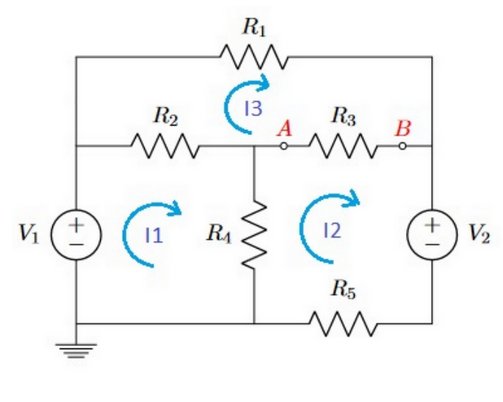

clc, clear, close all
format short g

r_out =50; %[Ω]
r1 = 100; %[Ω]
r2 = 220; %[Ω]
r3 = 330; %[Ω]
r4 = 33; %[Ω]
r5 = 120; %[Ω]

v1 = 9; %[V]
v2 = 5; %[V]

syms i1 i2 i3

m1 = simplify(253*i1-33*i2-220*i3 == v1)
m2 = simplify(-33*i1+483*i2-330*i3 == -v2)
m3 = simplify(-220*i1-330*i2+650*i3 == 0)
m = [-253 33 220; 33 -483 330; 22 33 -65];
n = [-9;5;0];
h = m\n;

i1 = h(1,1) %[A]
i2 = h(2,1) %[A]
i3 = h(3,1) %[A]

balance de potencia:

pr1 = (i3^2)*r1 %[W]
pr2 = ((i1-i3)^2)*r2 %[W]
pr3 = ((i3-i2)^2)*r3 %[W]
pr4 = ((i1-i2)^2)*r4 %[W]
pr5 = (i2^2)*r5 %[W]
pv1 = -v1*i1 %[W]
pv2 = v2*i2 %[W]
bp = pr1+pr2+pr3+pr4+pr5+pv1+pv2 % balance de potencia
